# **Problem 2.5**

**Dataset Generation and Visualization (a)**

We will use the Gaussian_Data_Gen function to generate a data set with the specified requirements:

mu1 = [1; 1];
mu2 = [10; 5];
mu3 = [11; 1];
s = [7, 4; 4, 5];
mu = cat(2, mu1, mu2, mu3);
sigma = cat(3, s, s, s);
% mu -> c x l
mu = permute(mu, [2, 1]);
% sigma -> c x l x l
sigma = permute(sigma, [3, 1, 2]);
P = [1/3; 1/3; 1/3];
N = 1000;
[X4, y_true] = Gaussian_Data_Gen(mu, sigma, P, N);
c1 = find(y_true==1);
c2 = find(y_true==2);
c3 = find(y_true==3);
disp(size(X4));

   999     2



disp(size(y_true));

   999     1



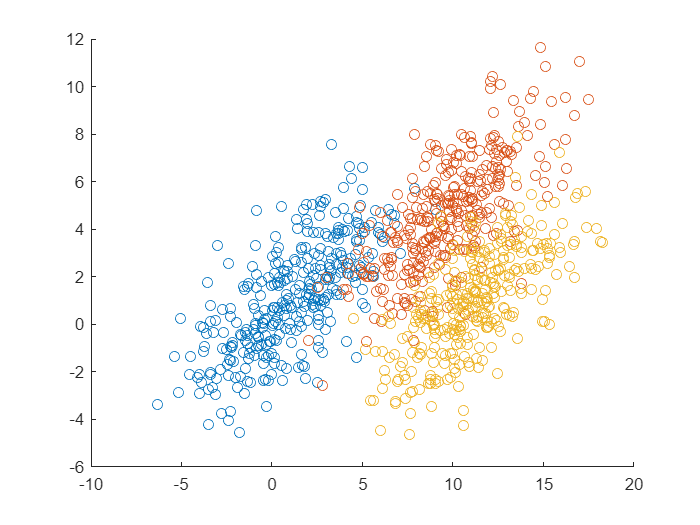

scatter(X4(c1,1), X4(c1, 2));
hold on;
scatter(X4(c2,1), X4(c2, 2));
hold on;
scatter(X4(c3,1), X4(c3, 2));
hold off;

**Applying Bayesian Classifier (b)**

We will use the helper function Bayesian_Classifier to fit a Bayesian Classifier on the data set:

pred_bayes = Bayesian_Classifier(mu, sigma, P, X4);
disp(size(pred_bayes));

   999     1



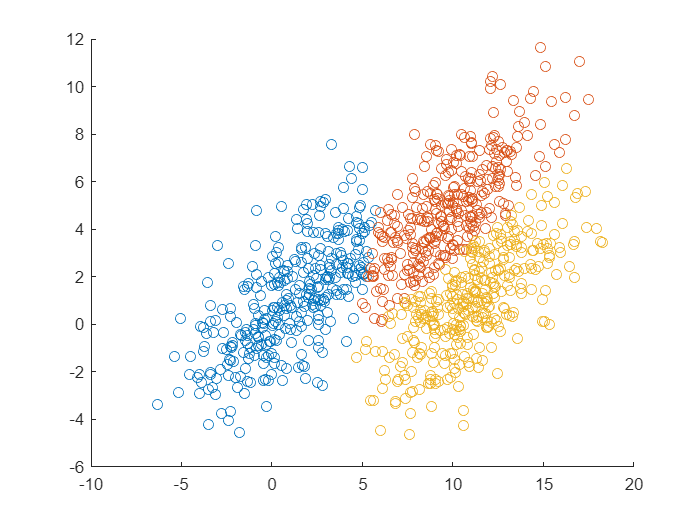

c1_bayes = find(pred_bayes==1);
c2_bayes = find(pred_bayes==2);
c3_bayes = find(pred_bayes==3);
scatter(X4(c1_bayes,1), X4(c1_bayes, 2));
hold on;
scatter(X4(c2_bayes,1), X4(c2_bayes, 2));
hold on;
scatter(X4(c3_bayes,1), X4(c3_bayes, 2));
hold off;

**Applying Euclidean Distance Classifier (b)**

We will use the helper function Euclidean_Dist_Classifier to fit a Euclidean Distance Classifier on the data set:

pred_euclidean_dist = Euclidean_Dist_Classifier(mu, X4);
disp(size(pred_euclidean_dist));

   999     1



c1_e_dist = find(pred_bayes==1);
c2_e_dist = find(pred_bayes==2);
c3_e_dist = find(pred_bayes==3);
scatter(X4(c1_e_dist,1), X4(c1_e_dist, 2));
hold on;
scatter(X4(c2_e_dist,1), X4(c2_e_dist, 2));
hold on;
scatter(X4(c3_e_dist,1), X4(c3_e_dist, 2));
hold off;

**Applying Mahalanobis Distance Classifier (b)**

Finally, we will use the helper function Mahalanobis_Dist_Classifier to fit a Mahalanobis Distance Classifier on the data set:

pred_mahalanobis_dist = Mahalanobis_Dist_Classifier(mu, sigma, X4);
disp(size(pred_mahalanobis_dist));

   999     1



c1_m_dist = find(pred_bayes==1);
c2_m_dist = find(pred_bayes==2);
c3_m_dist = find(pred_bayes==3);
scatter(X4(c1_m_dist,1), X4(c1_m_dist, 2));
hold on;
scatter(X4(c2_m_dist,1), X4(c2_m_dist, 2));
hold on;
scatter(X4(c3_m_dist,1), X4(c3_m_dist, 2));
hold off;

**Calculating Classification Error on each Classifier (c)**

We will compare 'y_true' with each of the predictions and count the number of mismatches and report the classification as a percentage of all the classifications performed:

fprintf(['Classification Error Percentages Report:\n' ...
    '\tBayesian Classifier: %f\n' ...
    '\tEuclidean Distance Classifier: %f\n' ...
    '\tMahalanobis Distance Classifier: %f\n'], ...
    100*mean(y_true~=pred_bayes), ...
    100*mean(y_true~=pred_euclidean_dist), ...
    100*mean(y_true~=pred_mahalanobis_dist));

Classification Error Percentages Report:
	Bayesian Classifier: 9.209209
	Euclidean Distance Classifier: 12.412412
	Mahalanobis Distance Classifier: 9.209209


Results:

- As expected, the Bayesian Classifier performs the best because it performs classification directly using available probability distribution functions. Any error in this classifier should be attributed to the randomness of the problem as this classifier is proven to perform optimally across all possible classifiers.

- Because the covariance matrices cannot be expressed in the form of $\sigma^2 I$, a Mahalanobis Distance Classifier performs exactly the same as a Bayesian Classifier using PDFs and is also optimal in error rate (because the Bayesian Classifier simplifies to a Mahalanobis Distance Classifier under these conditions). In fact we can check this using:

disp(length(find(pred_mahalanobis_dist~=pred_bayes)));

     0



- Additionally, because the covariance matrices cannot be expressed in the form of $\sigma^2 I$, Euclidean Distance Classifier has a higher rate of error since it does not take the difference of covariance and inter-dependability of variables into account. (It attempts to classify with the assumption of circle-like contours of same distance from the mean of each class when in reality, these contours form ellipsoids around the mean of each class).